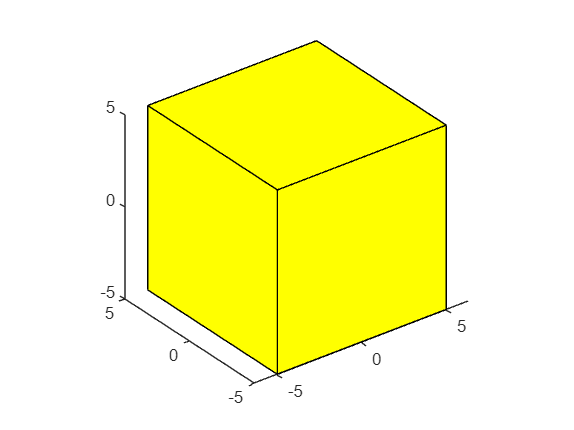

verticesCube = [
    -1, 1, 1, -1, -1, 1, 1, -1;
    -1, -1, 1, 1, -1, -1, 1, 1;
    -1, -1, -1, -1, 1, 1, 1, 1;
    1, 1, 1, 1, 1, 1, 1, 1
    ];

facesCube = [
    1, 2, 6, 5;
    2, 3, 7, 6;
    3, 4, 8, 7;
    4, 1, 5, 8;
    1, 2, 3, 4;
    5, 6, 7, 8
    ];

sizeMatrix = [
    5, 0, 0, 0;
    0, 5, 0, 0;
    0, 0, 5, 0;
    0, 0, 0, 1
    ];

newVertices = sizeMatrix * verticesCube;

DrawShape (newVertices, facesCube, 'y')
axis equal;
view(3);

function DrawShape(vertices, faces, color)
    patch('Vertices', (vertices(1:3,:)./vertices(4,:))','Faces', faces, 'FaceColor', color);

end